# Lag compensator design using phase margins

This livescript is a brief manual in support of how to do lag compensator design using frequency response methods, or specifically, by managing the phase margin as viewed in a Bode diagram. The aim is to help users understand core principles and steps, afterwhich they may prefer to use ***sisotool*** or other means to undertake designs on systems of their own choosing.

A logical supporting file is ***lag_design_with_bode.mlx*** which gives more comprehensive MATLAB source code and some examples. 

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Technical and mathematical background

- Simple gain design using phase margin criteria

- The design and operation of the app

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s*) and compensator *M(s)*.

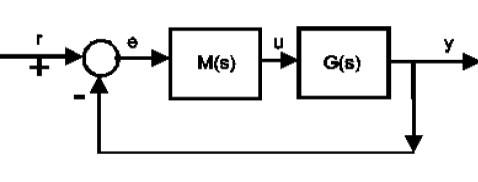

Readers should be familar with the file  **proportional_design_with_bode.mlx  **and/or** proportional_design_phase_margin.mlapp **for background on performance specifications which underpin design and also because this is a first step in a lag compensator design. 

%%%%%%  REMOVE COMMENTS TO RUN THE CODE AND OPEN THE RELEVANT TOOLBOX FILES
% proportional_design_with_bode
% proportional_design_phase_margin  

The closed-loop transfer function is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$ and the intention is to design the compensator M(s) to have the following stucture where*** K*** is chosen using simple proportional design methods.


$$M\left(s\right)=K\frac{s+a}{s+\frac{a}{r}}$$
      

Core properties of this compensator are that the low frequency gain is '***r***' times bigger than the high frequency gain and secondly, the system has negative phase in the regions near the corner frequencies: ***a, a/r***. In order for the phase characteristic not to interfere with PM computations, the gain cross over frequency $w_c$ is a decade to the right of the zero, so $a=\frac{w_c }{10}$. 

$M\left(s\right)\;=\;K\left(\frac{s+a}{s+\frac{a}{r}}\right)\;\;\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10r}}\right)$ ;                    $1\le r\le 10$.

## 2. Lag compensator design steps

For slower and detailed explanations and more flexible code and examples, see the file:

%% UNCOMMENT TO OPEN THIS FILE
% lag_design_with_bode

Here we assume  the design is based on specifications:

- Desired PM

- Desired low frequency gain.

A simple lag design tackles these in strict order. The intention is that the second step does not alter the PM achieved in the first, although we know that in practice we will lose 3-5 degrees of PM in step 2.

### 2.1 Simple gain design using phase margin criteria

We want to design the gain of the compensator the *M(s)* so that we have a desirable phase margin. The process can be systemised as follows.

- Decide desired PM and call this $\phi \ldotp$

- The PM is computed at the gain cross over frequency, so we can easily determine the frequency $w_c$ such that: $\arg \left(\textrm{GM}\right)=-180+\phi$. 

- Doing a proportional only design, chose the proportional ***K*** so that: $\left|\textrm{KG}\left(jw_c \right)\right|=1$

The app draws a horizontal line at the target PM so the user can see when this is achieved. The user can modify the gain in the Kp slider  to ensure the PM is achieved. The actual PM is displayed in the boxes at the bottom left. Save this value of ***K*** and also the associated crossover frequency $w_c$***. ***More guidance on this step is in the file ***proportional_design_phase_margin.mlapp.***

### 2.2 Adding the low frequency gain criteria

Having chosen the proportional gain, we add the lag component $\left(\frac{s+a}{s+\frac{a}{r}}\right)$which has a low frequency gain of ***r***. In general it is clumsy to form analytic expressions for low frequency gain/offset although it can be done as seen here. In a mechanistic design we choose:   $a=\frac{w_c }{10}$, where $w_c$ was computed in the previous step, section 2.1 above. The compensator is defined as: $M\left(s\right)\;=\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10r}}\right)$, with ***K*** also taken from the step above. What remains to be chosen is the scalar ***r***. Consequently the low frequency gain of the compensator is given as: $M\left(0\right)=\textrm{Kr}$

**Offset to steps**: For a simple fbk loop with system G(s) and compensator M(s) and no integrator, offset to a constant unity reference is given by the formula: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}$.  As $M\left(0\right)=\textrm{Kr}$ then we can write: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)\textrm{Kr}}\;\Rightarrow \;\textrm{Kr}=\frac{1}{G\left(0\right)}\left(\frac{1}{e_{\textrm{ss}} }-1\right)$ and thus determine the required value for ***r***.

**Offset to ramps** can also be useful and is commonly used in books to help create more precise criteria to enable systematic/explicit design.This formula is only useful if the system DOES include an integrator. Offset to a unit ramp is given as: $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)M\left(s\right)}$

With a ramp and lag compensator, as given above, this formula reduces to: $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)\textrm{Kr}}$; 

In both cases it is clear that, given a desired offset criteria, it is possible to specify the required ***r***, that is zero/pole ratio.

As the app is more for illustration, it focuses on comparing the simple proportional compensation with the lag compensation so that the user can see the change in low frequency gain/offset, alongside the changes in closed-loop behaviour, for different choices of ***r; ***only integer values are allowed for simplicity.  The actual offsets are stated in text boxes in the bottom left.

## 3. The design and operation of the app

### 3.1 Basic operation

The user can interact using the sliders and buttons in the top left. The figures update whenever any value is changed.

- Use the sliders in the yellow box to select the desired system. The current choice is displayed in the orange box in the bottom left.

- Use the sliders in the green box to select the desired phase margin (PM) and offset. These are shown in the figures using the dashed green lines.

- Use the sliders in the orange box to seelct the parameters ***Kp*** and ***r*** which define the Lag compensator. The corresponding  cross-over frequency $w_c$ is determined automatically within the code.

From these values the proportional compensation and lag compensation are full defined and figures are produced.

- The top figure is the Bode diagram, with both compensators and the uncompensated system.

- The actual PM is shown with the vertical pink dots. The desired PM is marked with the green dashed line.

- The closed-loop step response is shown in the bottom two figures (input and output) where the target offset is clearly marked in the output plot with the dashed green line.

- Core values such as offsets, margins (proportional and lag compensation respectively) are shown in the text boxes in the bottom left.

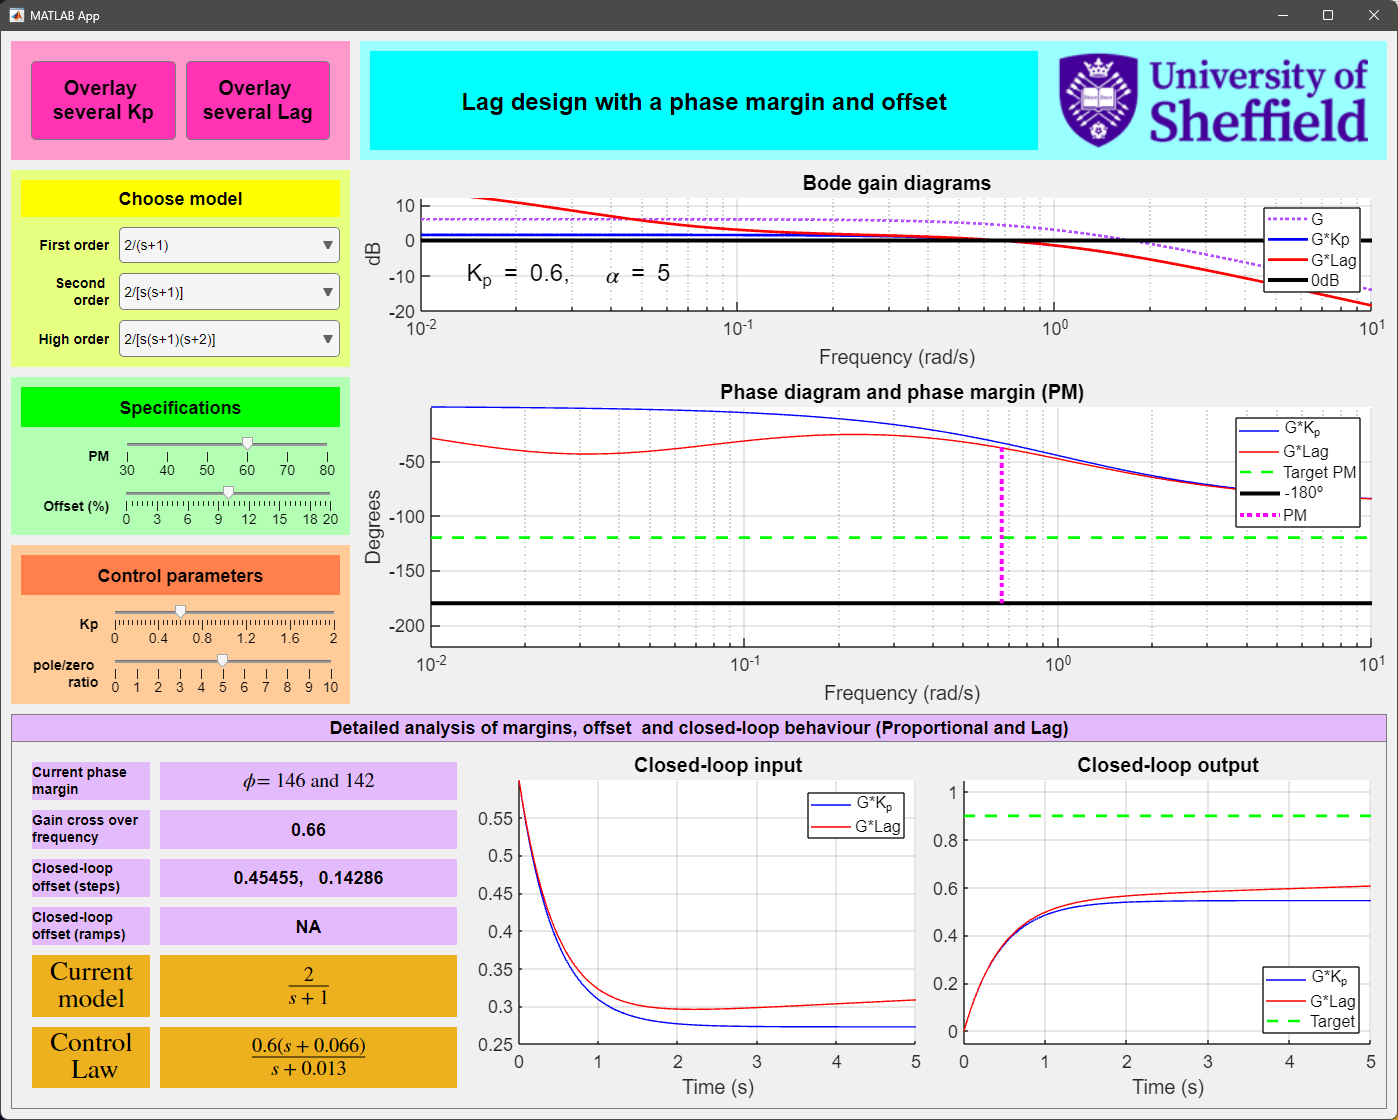

The user can attempt to meet specifications that they set (using green sliders) for a given system by making appropriate choices in the orange sliders. They can also observe clearly the differences between lag compensation and simple gain (proportional) design.

### 3.2 Overlay with alternative choices of proportional gain and/or lag pole/zero ratio

It may be interesting to see how the PM and closed-loop behaviour changes for different choices of gain by plotting all the corresponding data simultaneously. The pink button in the top left will replace all the plots with overlays. This allows the user to investigate proportional gain only which is the first step in a lag compensator design.

Similarly, the right button in  the top left will overlay multiple lag compensators. Here it is assumed that the proportional gain has already been selected and thus this button illustrates the impact of varying the pole/zero ratio (denoted by $\alpha$).

As soon as you select any other button, the plots revert to the original single choice of compensator.